#### Interpretation der Parameter in der Differentialgleichung:

Durch ein paar einfache Literaturrecherche stellt man schnell fest, dass das in der Aufgabenstellung angegebene Modell dem SI-Modell (Susceptible-Infective Model) im Gebiet der Epidemiologie entspricht. Nach dem Gegenüberstellen der Differentialgleichungen in den 2 Modellen ergibt sich bezüglich der Parameter folgendes:

k = sqrt(r * c * N), 

mit r als [Replikationsrate](https://de.wikipedia.org/wiki/Replikationsrate), c als Wechselwirkungsterm und N als die Gesamtbevölkerung.

clc
close 
clear

%% 

model = 'Ausbreitungsmodell';
load_system(model)
%Simulink.BlockDiagram.buildRapidAcceleratorTarget(model);
in = Simulink.SimulationInput(model);
%in = in.setModelParameter('SimulationMode', 'rapid-accelerator');
in = in.setModelParameter('EndTime', 100);

#### Bitte verändern Sie die Parameterwerte des Problems so dass sich interessante Zustände (stabiles/instabiles Systemverhalten) ergeben. Beschreiben Sie kurz, ob eine solche Parameterkombination möglich ist. 

- Veränderung y0


%in = in.setModelParameter('RapidAcceleratorUpToDateCheck', 'off');
y0 = 0.1:0.2:0.9;

for p = 1:1:length(y0)
    in(p) = Simulink.SimulationInput(model);
    in(p) = in(p).setVariable('y0', y0(p), 'Workspace', 'Ausbreitungsmodell');
end

out = parsim(in, 'ShowProgress', 'on');%Simulate dynamic system multiple times in parallel or serial, 否则需要写for loop & sim命令，一次一次的对仿真循环

[01-Feb-2021 22:38:57] Checking for availability of parallel pool...
[01-Feb-2021 22:38:57] Running simulations...
[01-Feb-2021 22:38:57] Completed 1 of 5 simulation runs
[01-Feb-2021 22:38:57] Completed 2 of 5 simulation runs
[01-Feb-2021 22:38:57] Completed 3 of 5 simulation runs
[01-Feb-2021 22:38:57] Completed 4 of 5 simulation runs
[01-Feb-2021 22:38:57] Completed 5 of 5 simulation runs


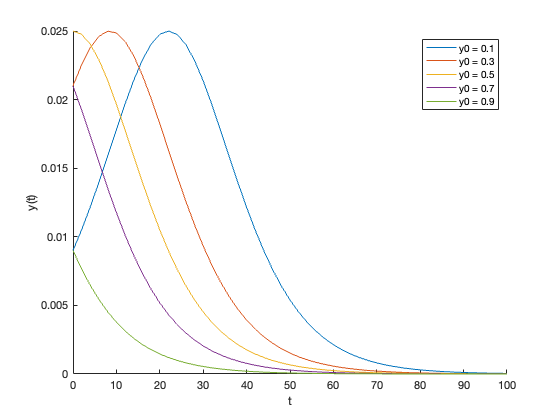


figure 
hold on

%将simulink所选log信号画出来
for p=1:1:length(out)
    plot(out(p).logsout{1}.Values)%要在simulink中将信号线log上！
    legendText{p} = ['y0 = ', num2str(y0(p))];
end
legend(legendText)
xlabel('t')
ylabel('y(t)')
saveas(gcf,'y(t)_entwicklung.jpg')

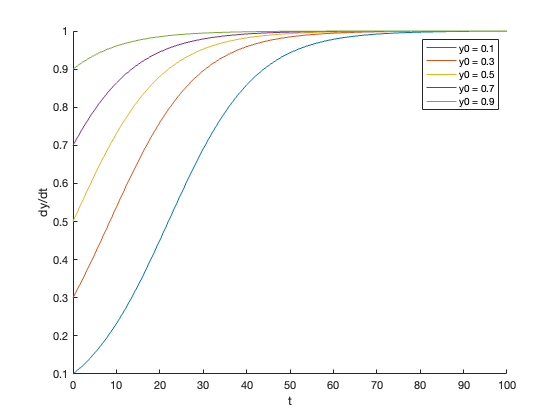


figure
hold on

for p=1:1:length(out)
    plot(out(p).logsout{2}.Values)
    legendText{p} = ['y0 = ', num2str(y0(p))];
end
legend(legendText)
xlabel('t')
ylabel('dy/dt')
saveas(gcf,'dydt_entwicklung.jpg')